clear variables; close all; clc;

## DKE Introduction to Bioinformatics 2022

# Hidden Markov Models 

The new corona virus contains just a few genes, one of them is a nucleocapsid phosphoprotein, known as N.  The accession code for the RNA for the whole Coronavirus 2 genome is NC_045512.  The N protein can be found in the region 28274...29533.

- First download the full sequence, extract the part of the sequence for the N protein and make a nucleotide density plot with a suitable window size. Showing the distribution of each base across the sequence and also the AT and GC pairs. 

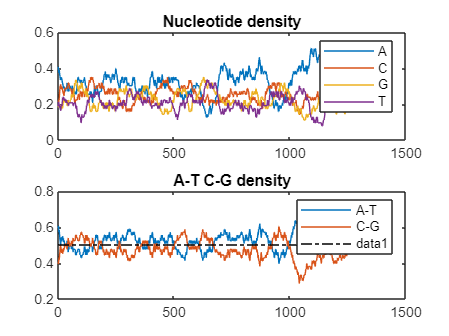

Corona2 = getgenbank('NC_045512');
N = Corona2.Sequence(28274:29533);
clear Corona2;
length_N = length(N); 
figure
[DENSITY, HIGHCG] = ntdensity(N,'CGTHRESHOLD',0.5);

LOWCG = setdiff(1:length_N,HIGHCG);

        2. To start training a hidden Markov model we first need to estimate the E and T matrices. *Explain what these matrices are. *

TRANSITION MATRIX = the probability of a state change:

EMISSION PROBABILITY =  symbol probability distribution in a certain state

        3.  Our Hidden Markov model will have 2 states, and we expect transitions between states to be rare. Use this information to estimate T. 

T_guess = [   
        0.9 0.1;
        0.1 0.9
];

        4. Looking at the plot of the distribution of bases, identify 2 regions with different patterns of expression. Calculate the proportion of each base in each of these two regions and put them together to make an initial estimate for E.

HN = string(N(HIGHCG)); lhn = length(HIGHCG);
LN = string(N(LOWCG)); lln = length(LOWCG);
c1 = [count(HN,'a'), count(HN,'c'), count(HN,'g'), count(HN,'t')] ./ lhn;
c2 = [count(LN,'a'), count(LN,'c'), count(LN,'g'), count(LN,'t')] ./ lln;
E_guess = [c1 ; c2];

        5. Before we can train the hidden Markov model we need to turn the sequence into integers instead of characters – use **nt2int** to do this. 

int_seq = nt2int(N);

        6. Now we can train our hmm using **hmmtrain** (NB. to speed this up you can change the tolerance parameter). This gives us the learnt E and T matrices based on this sequence. How do these vary from your initial guesses? 

[T_est, E_est] = hmmtrain(int_seq,T_guess,E_guess,"tolerance",1e-3) 

T_est =     0.6395    0.3605
    0.2399    0.7601


E_est =     0.0209    0.2646    0.2882    0.4263
    0.5153    0.2402    0.1782    0.0663


        7. To look at how this HMM would segment your sequence, use the function **hmmviterbi** to generate the estimated states from this sequence.  

states = hmmviterbi(int_seq, T_est, E_est)

states =      2     1     1     1     1     1     1     2     2     2     2     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     1     2     2     2     2     2     2     2     2     2     1     1     2     2     1     1     1


        8. Using the **hold** function add these states onto the **ntdensity** plot. How does this help your interpretation of the states? Can you explain what the two states mean? 

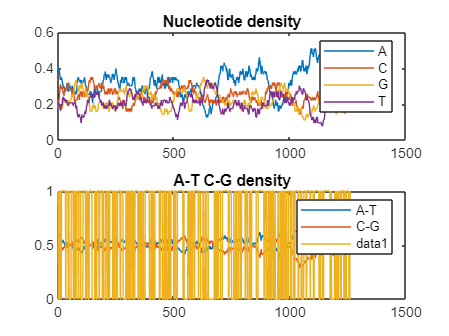

figure
ntdensity(N)
hold on;
plot(states-1);
hold off;

**Assignment:**

Try building HMMs with different numbers of states on this sequence.  Which number of states works best?  Explain your best model, interpreting the states (explain how they are different from each other, no biological interpretation needed).  